%clear variables;

out = run_experiment('experiments/stringmain_n_10_fe.mat');

Iteration: 1  W max:4.347e-04  Error:1.308e-04  S: 4.222898e-03  Alignment:NaN Length: 2.714439e-01
Iteration: 101  W max:1.379e-02  Error:1.034e-04  S: 3.342557e-02  Alignment:0.999960 Length: 2.745128e-01
Iteration: 201  W max:1.244e-02  Error:7.966e-05  S: 2.133158e-02  Alignment:0.999939 Length: 2.776700e-01
Iteration: 301  W max:1.169e-02  Error:4.901e-05  S: 1.618521e-02  Alignment:0.999890 Length: 2.796959e-01
Iteration: 401  W max:1.141e-02  Error:2.817e-05  S: 1.380092e-02  Alignment:0.999790 Length: 2.806888e-01
Iteration: 501  W max:1.123e-02  Error:2.337e-05  S: 1.285189e-02  Alignment:0.999702 Length: 2.812836e-01
Iteration: 601  W max:1.116e-02  Error:1.979e-05  S: 1.235705e-02  Alignment:0.999686 Length: 2.815627e-01
Iteration: 701  W max:1.115e-02  Error:1.916e-05  S: 1.215038e-02  Alignment:0.999613 Length: 2.819937e-01
Iteration: 801  W max:1.114e-02  Error:1.428e-05  S: 1.191415e-02  Alignment:0.999525 Length: 2.824490e-01
Iteration: 901  W max:1.105e-02  Error:1.463

v10fe = out.err_arr;
w10fe = out.W_arr;
out = run_experiment('experiments/stringmain_n_20_fe.mat');
v20fe = out.err_arr;
w20fe = out.W_arr;
out = run_experiment('experiments/stringmain_n_40_fe.mat');
v40fe = out.err_arr;
w40fe = out.W_arr;
out = run_experiment('experiments/stringmain_n_80_fe.mat');
v80fe = out.err_arr;
w80fe = out.W_arr;

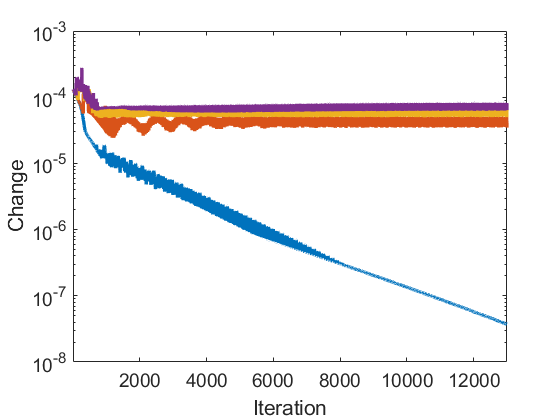

range = 1:12995;
semilogy(range, v10fe(range), range, v20fe(range), range, v40fe(range), range, v80fe(range), 'LineWidth', 2.5)
axis([range(1) range(end) 1e-8 1e-3])
%legend('n=10','n=20','n=40','n=80', 'Location', 'best')
xlabel('Iteration')
ylabel('Change')
set(gca, "FontSize", 14);
saveas(gcf,'figures/3a.png')

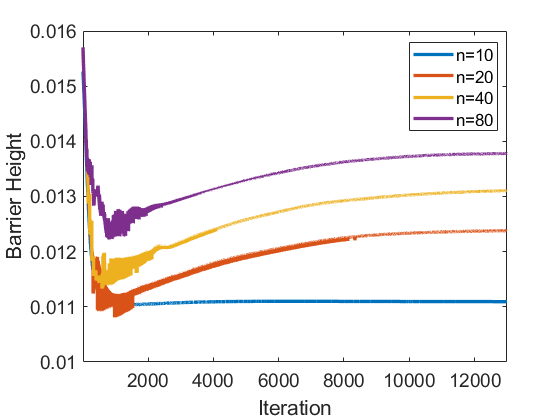

range = 2:12995;
plot(range, w10fe(range), range, w20fe(range), range, w40fe(range), range, w80fe(range), 'LineWidth', 2.5)
axis([range(1) range(end) 0.01 0.016])
legend('n=10','n=20','n=40','n=80', 'Location', 'best')
xlabel('Iteration')
ylabel('Barrier Height')
set(gca, "FontSize", 14);
saveas(gcf,'figures/3b.png')